This script describe how to run the simulation of FLIM experiments to look at how well our program deals with background correction in fitting as well as calculation of empirical lifetime. By adding different amount of background noise into the simulated histograms and letting them run through our fitting and calculation pipeline, we will compare the **spc.fit.backcorr** term with our added background and evaluate how well our program is able to resolve the background. We will also look at whether and how different size of sample (photon count) influence the performance.

First I'll generate the population of Ach sensor photons based on empirically collected fitting parameters. Here we will assume the Ach sensor fluorescence follows double exponential decay. 

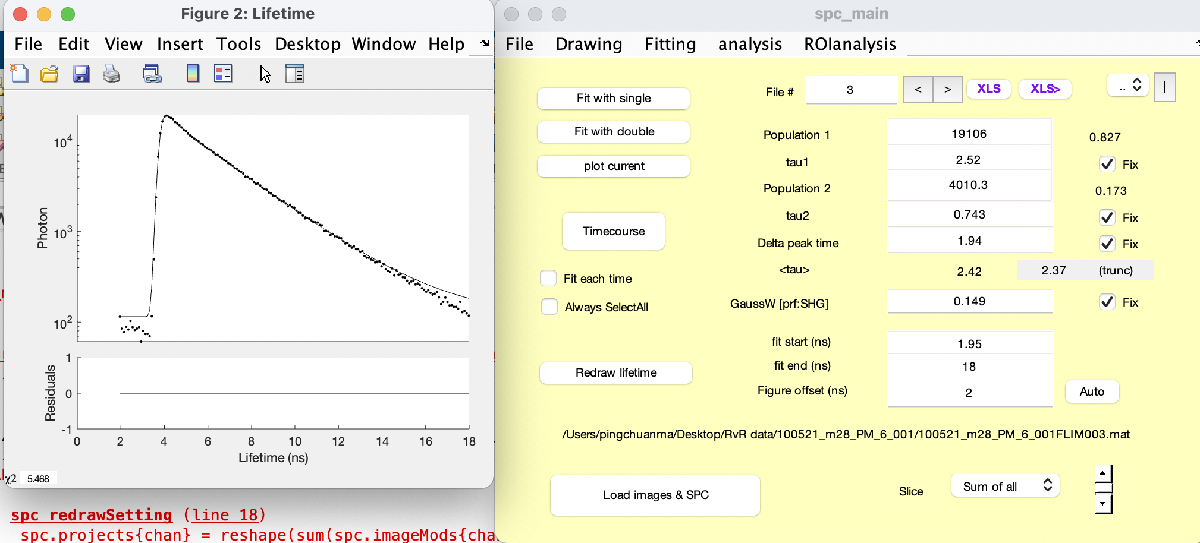

tau1=2.5186; tau2=0.7425; p1=0.8265; p2=0.1735; TP=100000; % Peak photon 100000
GenPop256(TP,p1,p2,tau1,tau2);

'GenPop256' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/pingchuanma/Documents/MATLAB/simulation

Change the MATLAB current folder or add its folder to the MATLAB path.

load('DoubleExpPop256.mat');
save('DoubleExpPop256_1019','Population');

This section is to sample the histograms to mimick empirically collected data from FLIM experiments, with different background.

First I'll sample histograms with different photon sizes, but without any autofluorescence, and after-pulse. Then for each photon size, I'll add different background into each channel of the histograms.

Other data used: 

prf: 

Autofluorescence: 

Photon sizes: 100000, 300000, 600000;

Background sizes: 20/channel, 50/channel, 100/channel;

GeneratedPopulation='DoubleExpPop256_1019'; 
mkdir('back_corr_samples_noAF')
filepath='/Users/pingchuanma/Documents/MATLAB/simulation/back_corr_samples_noAF';
samplesize=[100000 300000 600000];
for i=1:3
    mkdir([filepath,'/',num2str(samplesize(i))])
    for j=1:100
        FLIMsim256_noauto(samplesize(i),3000,18300, GeneratedPopulation);
        load('FLIMSimulation_pm.mat');
        samplename=[filepath,'/',num2str(samplesize(i)),'/',num2str(j)];
        save(samplename,'n','xout');
    end
end

Next I'll add different amount of background into each channels of the histogram.

filepath='/Users/pingchuanma/Documents/MATLAB/simulation/back_corr_samples_noAf';
samplesize=[100000 300000 600000];
for i=1:3
    cd([filepath,'/',num2str(samplesize(i))])
    for j=1:100
        load([num2str(j),'.mat'])
        n1=n+20;
        n2=n+50;
        n3=n+100;
        samplename1=[num2str(j),'_20.mat'];
        samplename2=[num2str(j),'_50.mat'];
        samplename3=[num2str(j),'_100.mat'];
        samplename4=[num2str(j),'_0.mat'];
        save(samplename1,'n1');
        save(samplename2,'n2');
        save(samplename3,'n3');
        save(samplename4,'n');
    end
    
end

Next is doing the fitting.

I'm doing prf fitting, using the exact prf I was using for sampling.

filepath='/Users/pingchuanma/Documents/MATLAB/simulation/back_corr_samples_noAf';
samplesize=[100000 300000 600000];
chan=1;
for i=3
    cd([filepath,'/',num2str(samplesize(i))]);
    matfiles_0=dir('*_0.mat');
    matfiles_20=dir('*_20.mat');
    matfiles_50=dir('*_50.mat');
    matfiles_100=dir('*_100.mat');
    for j=1:100
        filename=matfiles_0(j).name;
        load(filename);
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_0(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_0(j)=spc.fits{chan}.avgTau;
        emp_tau_0(j)=spc.fits{1}.EmpTauTrunc;
        chi2_0(j)=spc.fits{chan}.redchisq;
        backcorr_0(j)=spc.fit.backCorr;
    end
    for j=1:100
        filename=matfiles_20(j).name;
        load(filename);
        spc.lifetimes{1,1} = n1;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_20(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_20(j)=spc.fits{chan}.avgTau;
        emp_tau_20(j)=spc.fits{1}.EmpTauTrunc;
        chi2_20(j)=spc.fits{chan}.redchisq;
        backcorr_20(j)=spc.fit.backCorr;
    end
    for j=1:100
        filename=matfiles_50(j).name;
        load(filename);
        spc.lifetimes{1,1} = n2;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_50(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_50(j)=spc.fits{chan}.avgTau;
        emp_tau_50(j)=spc.fits{1}.EmpTauTrunc;
        chi2_50(j)=spc.fits{chan}.redchisq;
        backcorr_50(j)=spc.fit.backCorr;
    end
    for j=1:100
        filename=matfiles_100(j).name;
        load(filename);
        spc.lifetimes{1,1} = n3;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_100(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_100(j)=spc.fits{chan}.avgTau;
        emp_tau_100(j)=spc.fits{1}.EmpTauTrunc;
        chi2_100(j)=spc.fits{chan}.redchisq;
        backcorr_100(j)=spc.fit.backCorr;
    end
end

fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0



SaveResultName=['backcorr_simulation_result_',num2str(i)];
save(SaveResultName,"backcorr_100","chi2_100","emp_tau_100","avg_tau_fit_100","p1_100","backcorr_50","chi2_50","emp_tau_50","avg_tau_fit_50","p1_50",...
    "backcorr_20","chi2_20","emp_tau_20","avg_tau_fit_20","p1_20","backcorr_0","chi2_0","emp_tau_0","avg_tau_fit_0","p1_0");


Plotting the results.

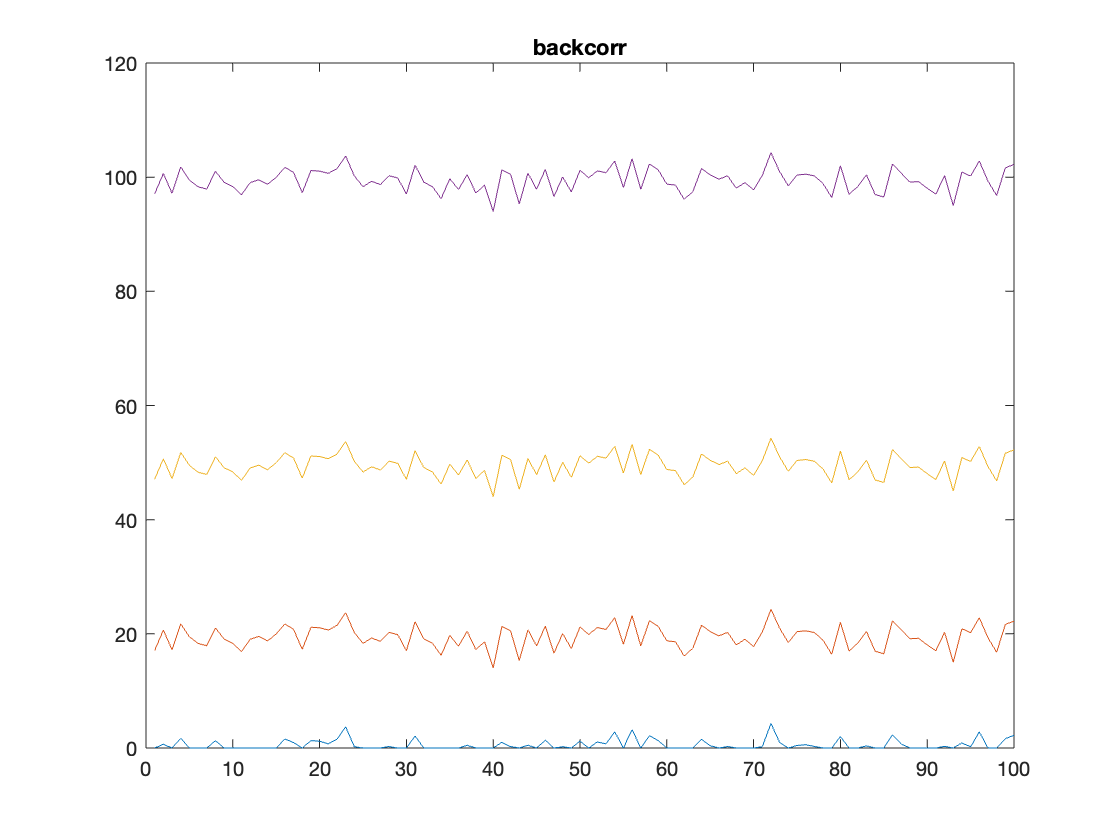

figure
plot(backcorr_0)
hold on
plot(backcorr_20)
hold on
plot(backcorr_50)
hold on
plot(backcorr_100)
title('backcorr')

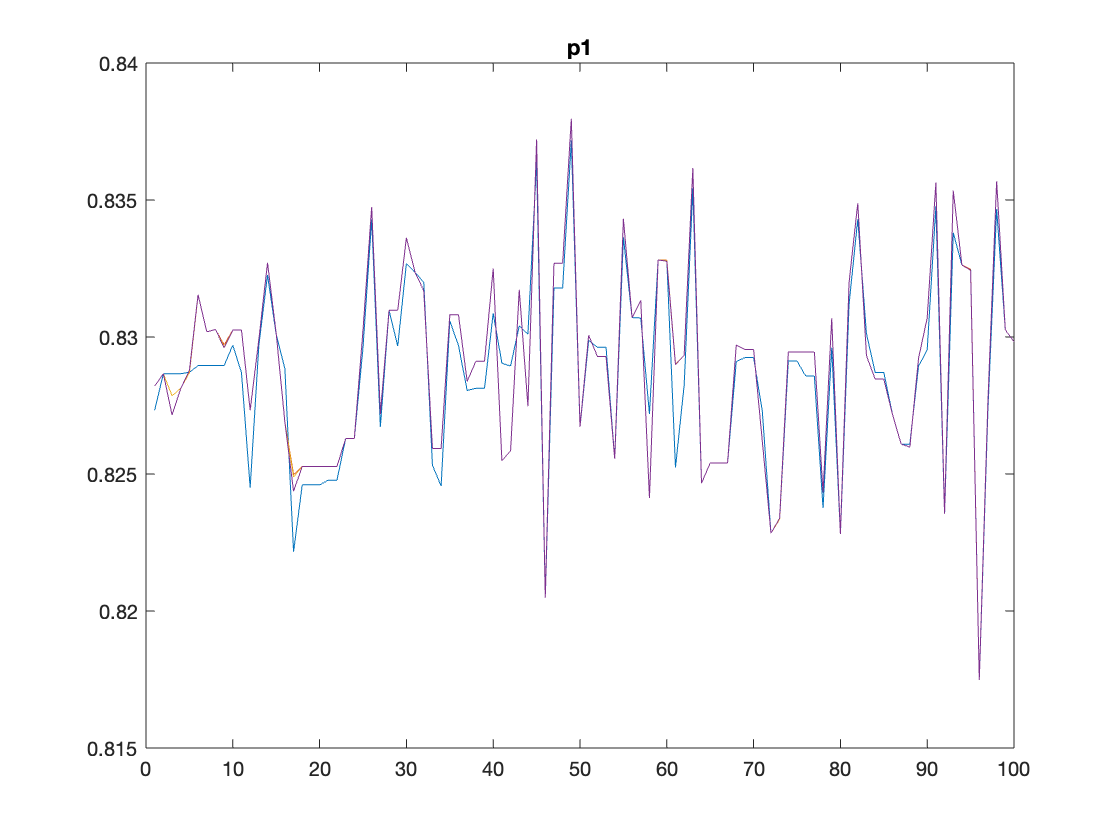


figure
plot(p1_0)
hold on
plot(p1_20)
hold on
plot(p1_50)
hold on
plot(p1_100)
title('p1')

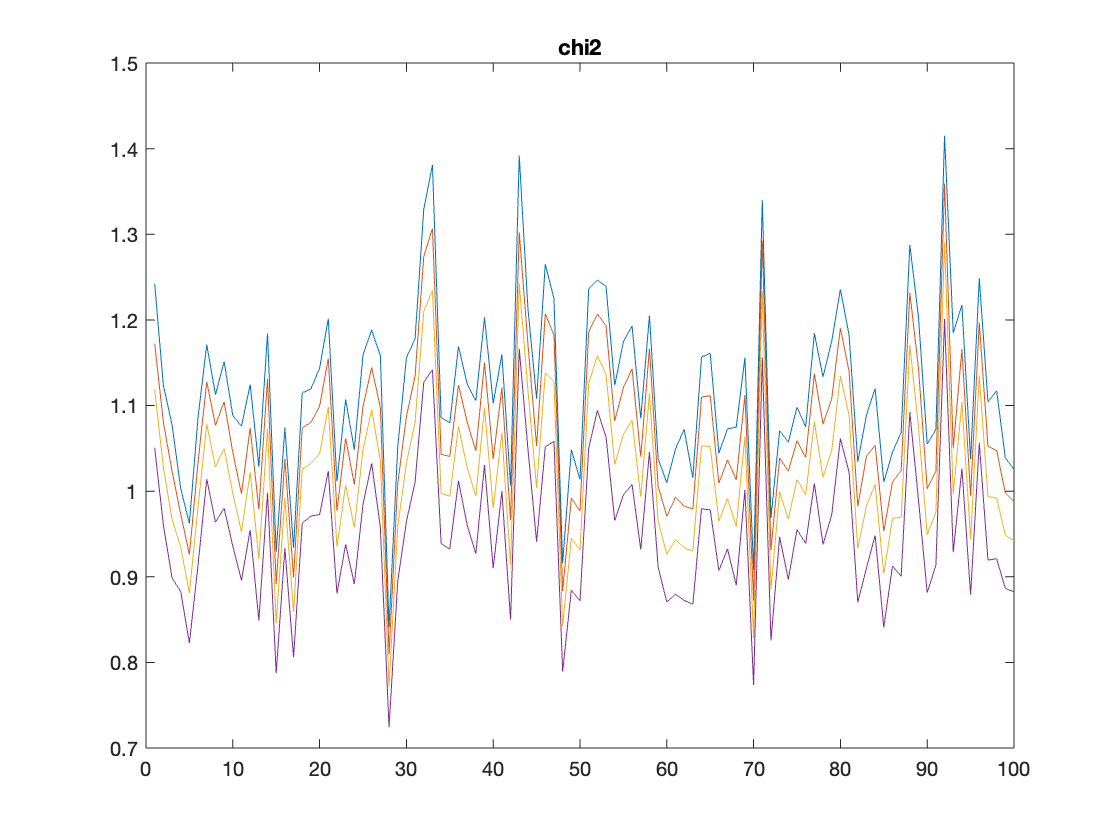


figure
plot(chi2_0)
hold on
plot(chi2_20)
hold on
plot(chi2_50)
hold on
plot(chi2_100)
title('chi2')

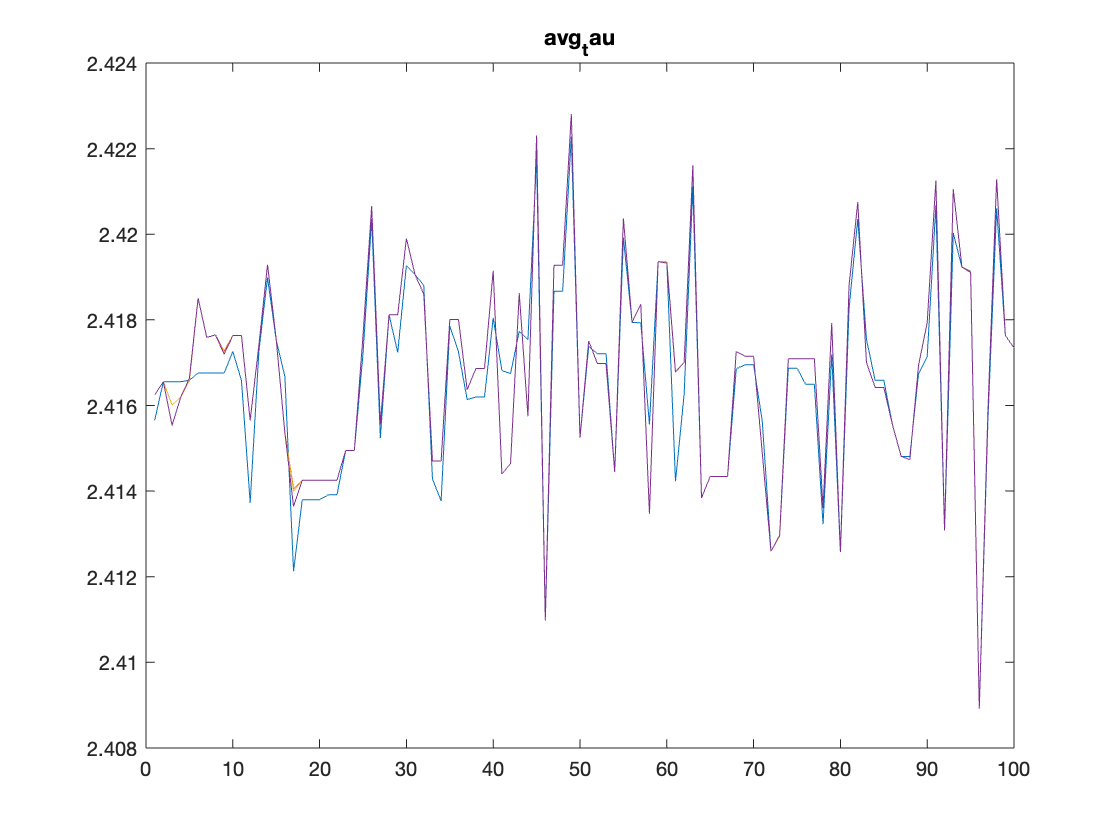


figure
plot(avg_tau_fit_0)
hold on
plot(avg_tau_fit_20)
hold on
plot(avg_tau_fit_50)
hold on
plot(avg_tau_fit_100)
title('avg_tau')

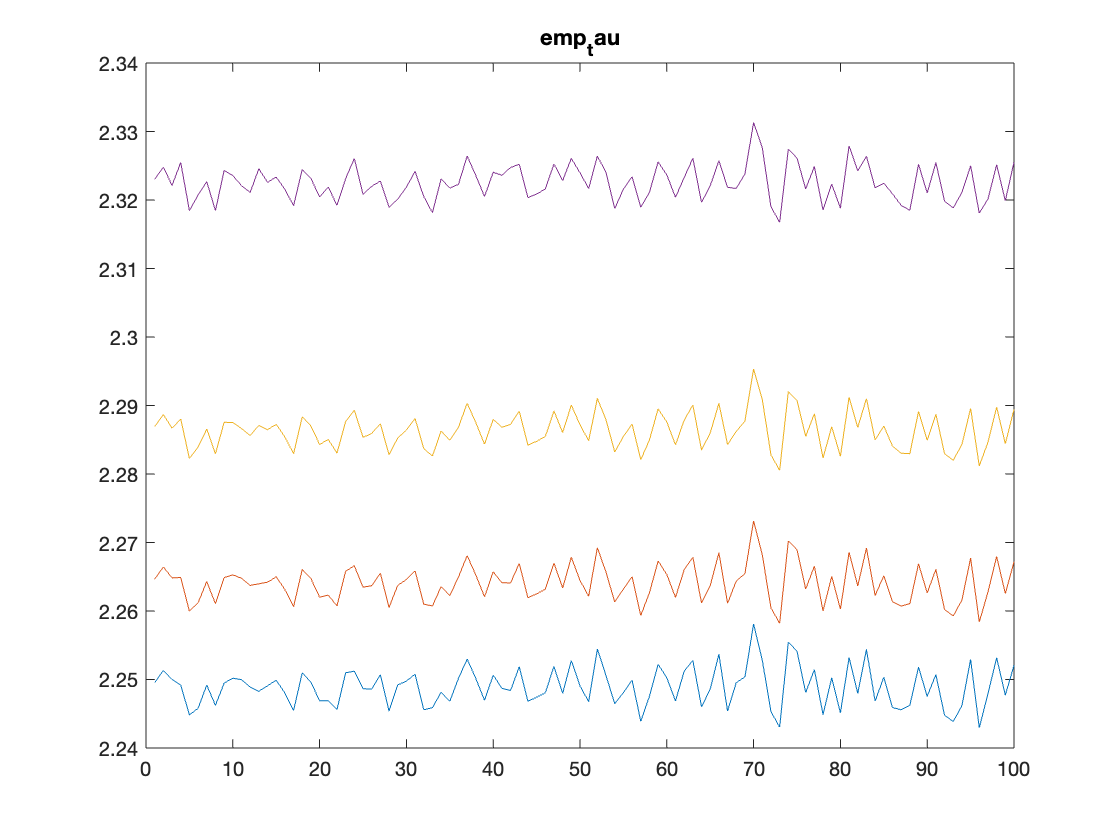



figure
plot(emp_tau_0)
hold on
plot(emp_tau_20)
hold on
plot(emp_tau_50)
hold on
plot(emp_tau_100)
title('emp_tau')

It looks like that the program is dealing with the background pretty well.